# Homework 2:Classification challenge

Classify the sequence of digits in "xTest2" as well as you can using a neural-network algorithm. For this task, you may use any package/library to design and train the network. Upload your sequence of classifications as a CSV-file "classifications.csv". If you classify the $\mu^{th}$pattern as the digit 6, then write 6 in the $\mu^{th}$ entry of the CSV-file, and in the same way for the other digits. It does not matter whether the sequence is written as a row or a column. Use the upload button at the top of this page to upload your file.

## load data

clc
clear
xTest2 = loadmnist2();
[xTrain, tTrain, xValid, tValid, xTest, tTest] = LoadMNIST(3);

Preparing MNIST data...
MNIST data preparation complete.


size(xTrain);
size(xTest2);
% one_digit = xTest2(:,:,:,3);

## Define Network Architecture

layers_1 = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

## Training Options

options_1 = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{xValid,tValid}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress')

options_1 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 4
                   MiniBatchSize: 128
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[28×28×1×10000 uint8]  [10000×1 categorical]}
             ValidationFrequency: 30
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerL

## Train Network

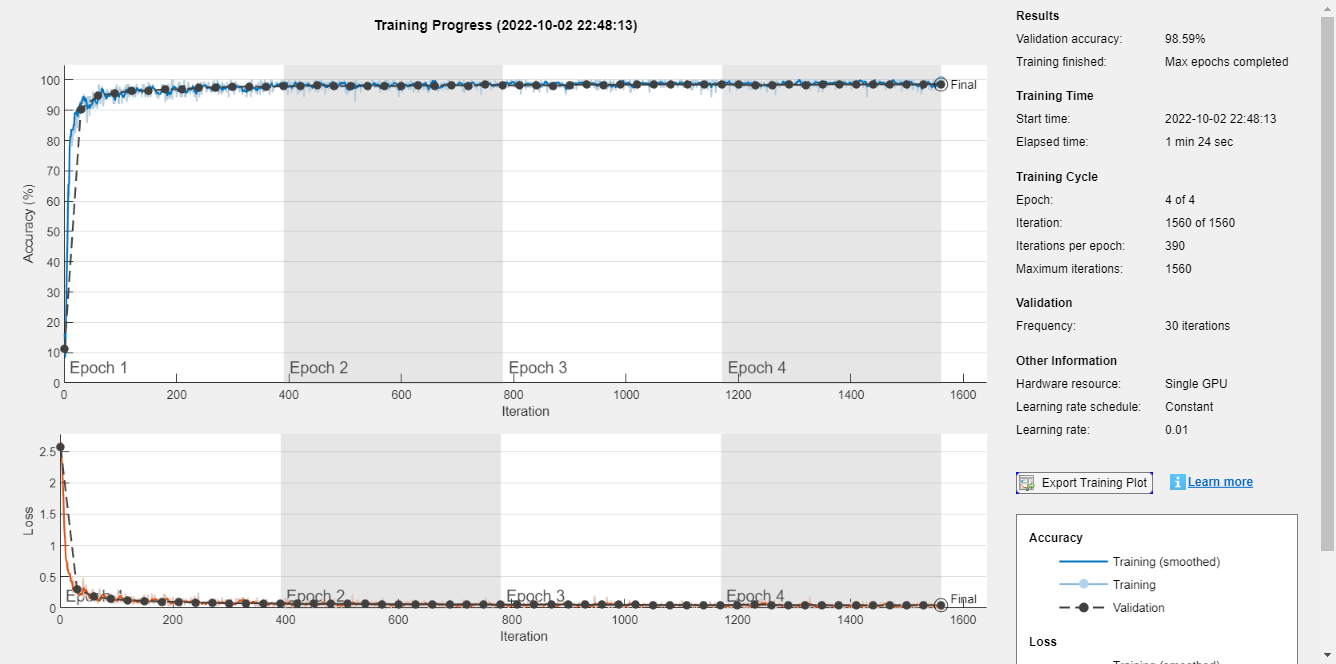

net_1 = trainNetwork(xTrain,tTrain,layers_1,options_1);

## Classify Validation Images and Compute Accuracy

tValid_pred_1 = classify(net_1, xValid);
accuracy_Val_1 = sum(tValid_pred_1 == tValid)/numel(tValid);

tTest_pred_1 = classify(net_1, xTest);
accuracy_Test_1 = sum(tTest_pred_1 == tTest)/numel(tTest);

tTest2_pred_1 = classify(net_1, xTest2);
disp(accuracy_Val_1)

    0.9859



disp(accuracy_Test_1)

    0.9863



writematrix(tTest2_pred_1,"classifications.csv")